# Single-Phase Photovoltaic (PV) System

## **Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Introduction

A single-phase photovoltaic (PV) system converts solar energy into DC power, which is then processed by an Inverter to produce AC power for grid integration or local loads. One of the primary challenges in these systems is the generation of second-order harmonics, resulting from double-frequency power oscillations inherent in single-phase AC systems. These harmonics can cause increased total harmonic distortion (THD).

To eliminate second harmonics, techniques such as notch filtering, Proportional-Integral control, dual-loop control systems, and DC-link decoupling strategies are implemented.

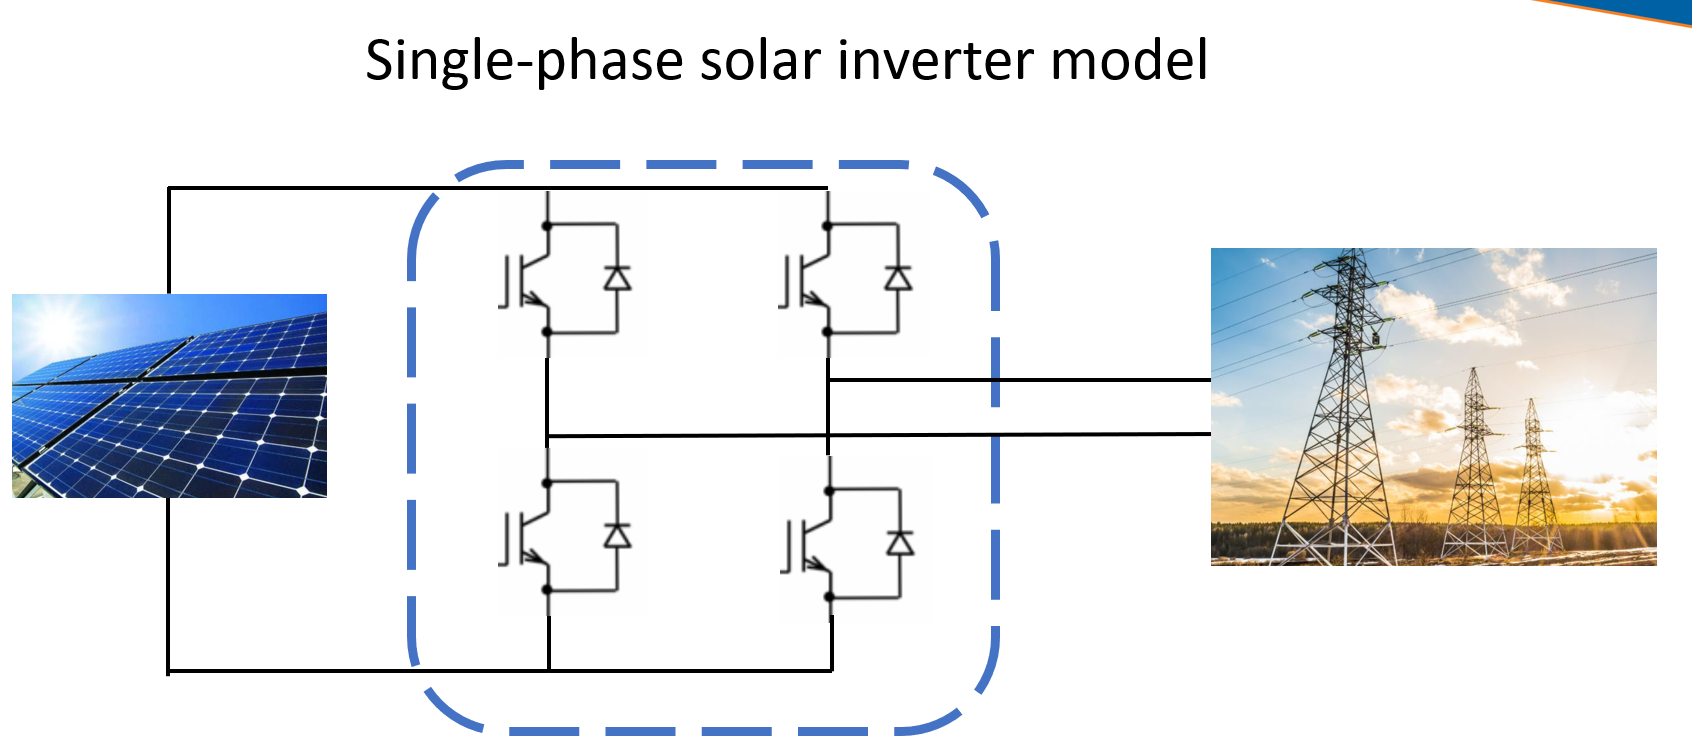

The structure of the Single-phase PV system 

## Pulsating Power

One key difference between a three-phase PV power system and a single-phase PV power system is the presence of “pulsating power.” Since both the grid voltage and the inverter output are sinusoidal signals, the instantaneous power $p=U\times \;I$ will contain a second-order harmonic component. This harmonic reflects back to the PV panel, causing its voltage to fluctuate. As a result, the PV system cannot maintain a stable operating point at Maximum Power Point Tracking (MPPT), which reduces energy efficiency, shortens the equipment lifespan, and degrades the quality of the electricity supplied. 

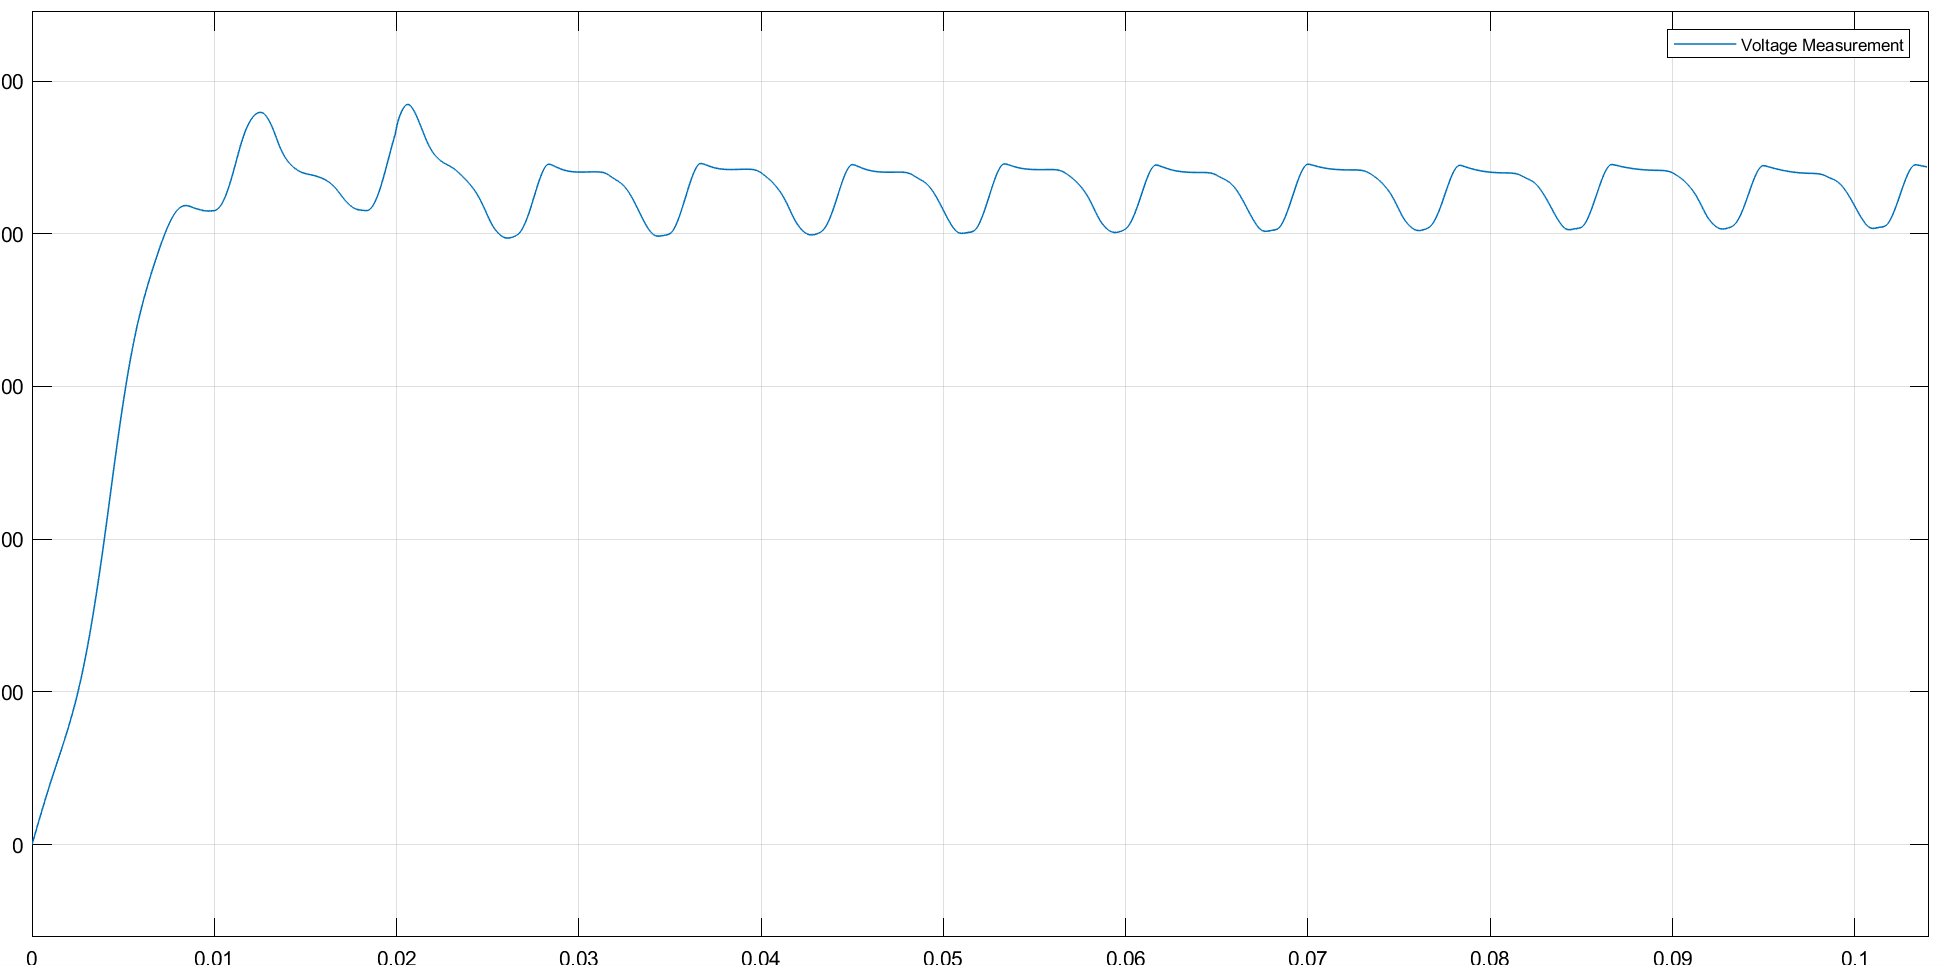

The second-order(120 Hz) harmonics reflect on the PV voltage

To address this issue, a larger capacitor and a boost converter are introduced. The boost converter acts as a filter, removing second-order harmonics from the inverter output. At the same time, the large capacitor absorbs the pulsating power, further reducing the impact of these harmonics.

## Circuit

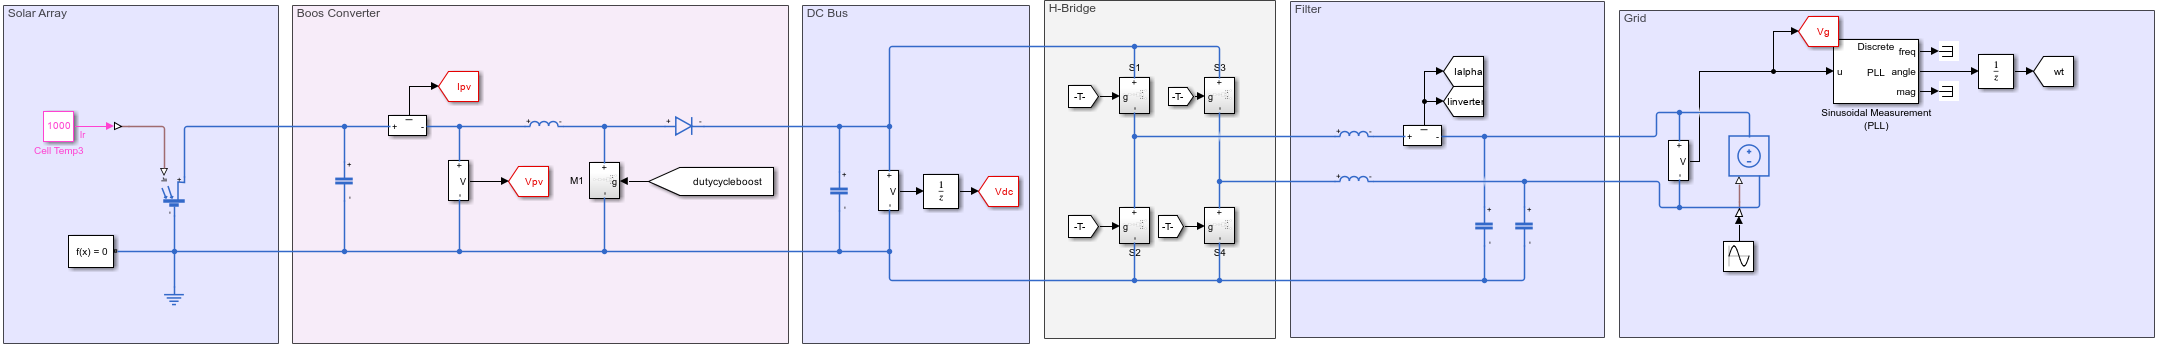The circuit above shows the solar array connected to the power grid through a three-phase Inverter and a filter. 

Click the button below to learn more about different sections of the model: 

switchRectifier("No Selection");

### Solar Panel

Photovoltaic (PV) technology is a transformative approach to generating electricity that harnesses the sun's power through solar panels made of semiconductor materials. This technology is pivotal in the move towards sustainable energy solutions because it provides a clean, renewable source of energy that significantly reduces greenhouse gas emissions compared to traditional fossil fuels.

Here is a picture of the PV module in the real world:

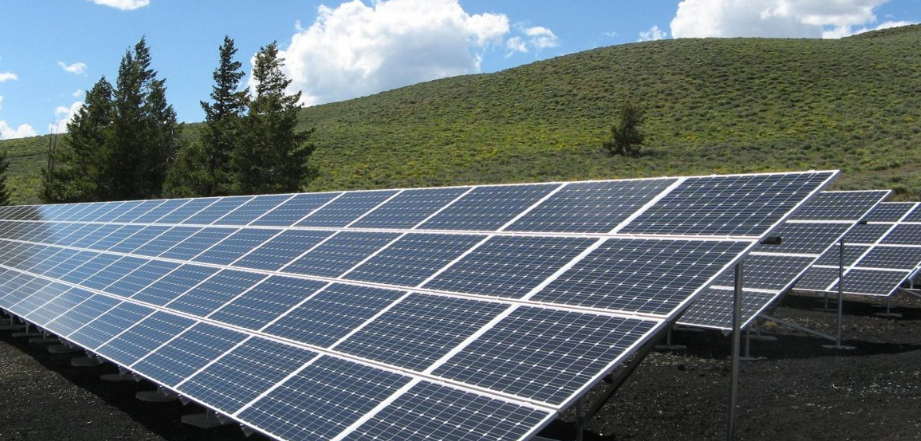

**A current-voltage **curve illustrates the relationship between the current and voltage under proper irradiance and temperature conditions (normally defined as 1000 $w/m^2$ and 25 degrees Celsius, respectively).

The following simulink model shows the detailed structure of the PV model: 

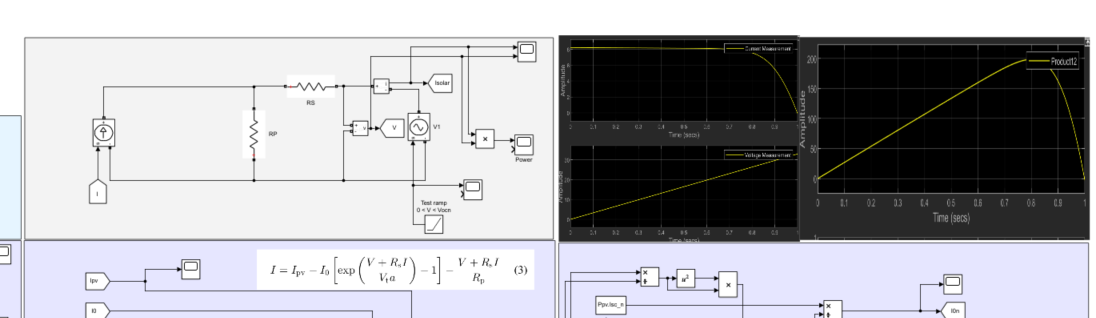

Click below to further explore this model.

 
open_system('model/PVmodule.slx')

Now, you can use the following sliders to adjust the irradiance and temperature conditions of the PV cell. See how these changes impact the **current-voltage** and **voltage-power** curves.

Irradiance=1000;
Temperature=50;
 
pv_curves(Irradiance, Temperature);

### Single-Phase PV Circuit Simulation

Let's turn our attention back to the full PV circuit.

Click the **Open & Run** button below and explore the model.

After the simulation is complete **(allow a few minutes)**, you will get the following four plots:

- DC Output Voltage

- Inverter Current

- Output Power

- PV Voltage

open_system('model/one_phase_PV_Final.slx')
warning('off','all')
simOut = sim('model/one_phase_PV_Final.slx','ReturnWorkspaceOutputs','on');
runmodel_onephasePV(simOut);

### Grid Connection

For simulation purposes, to ensure the **stability** and **quality** of the power grid, the only requirement for the inverter’s AC output is that its **frequency **matches the grid’s frequency and **phase angle**. A Phase-Locked Loop (PLL) strategy is used to measure grid frequency. At this stage, we do not need to examine the internal principles or operation of the PLL.

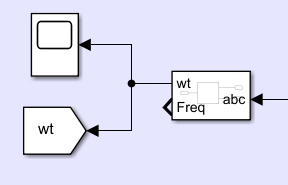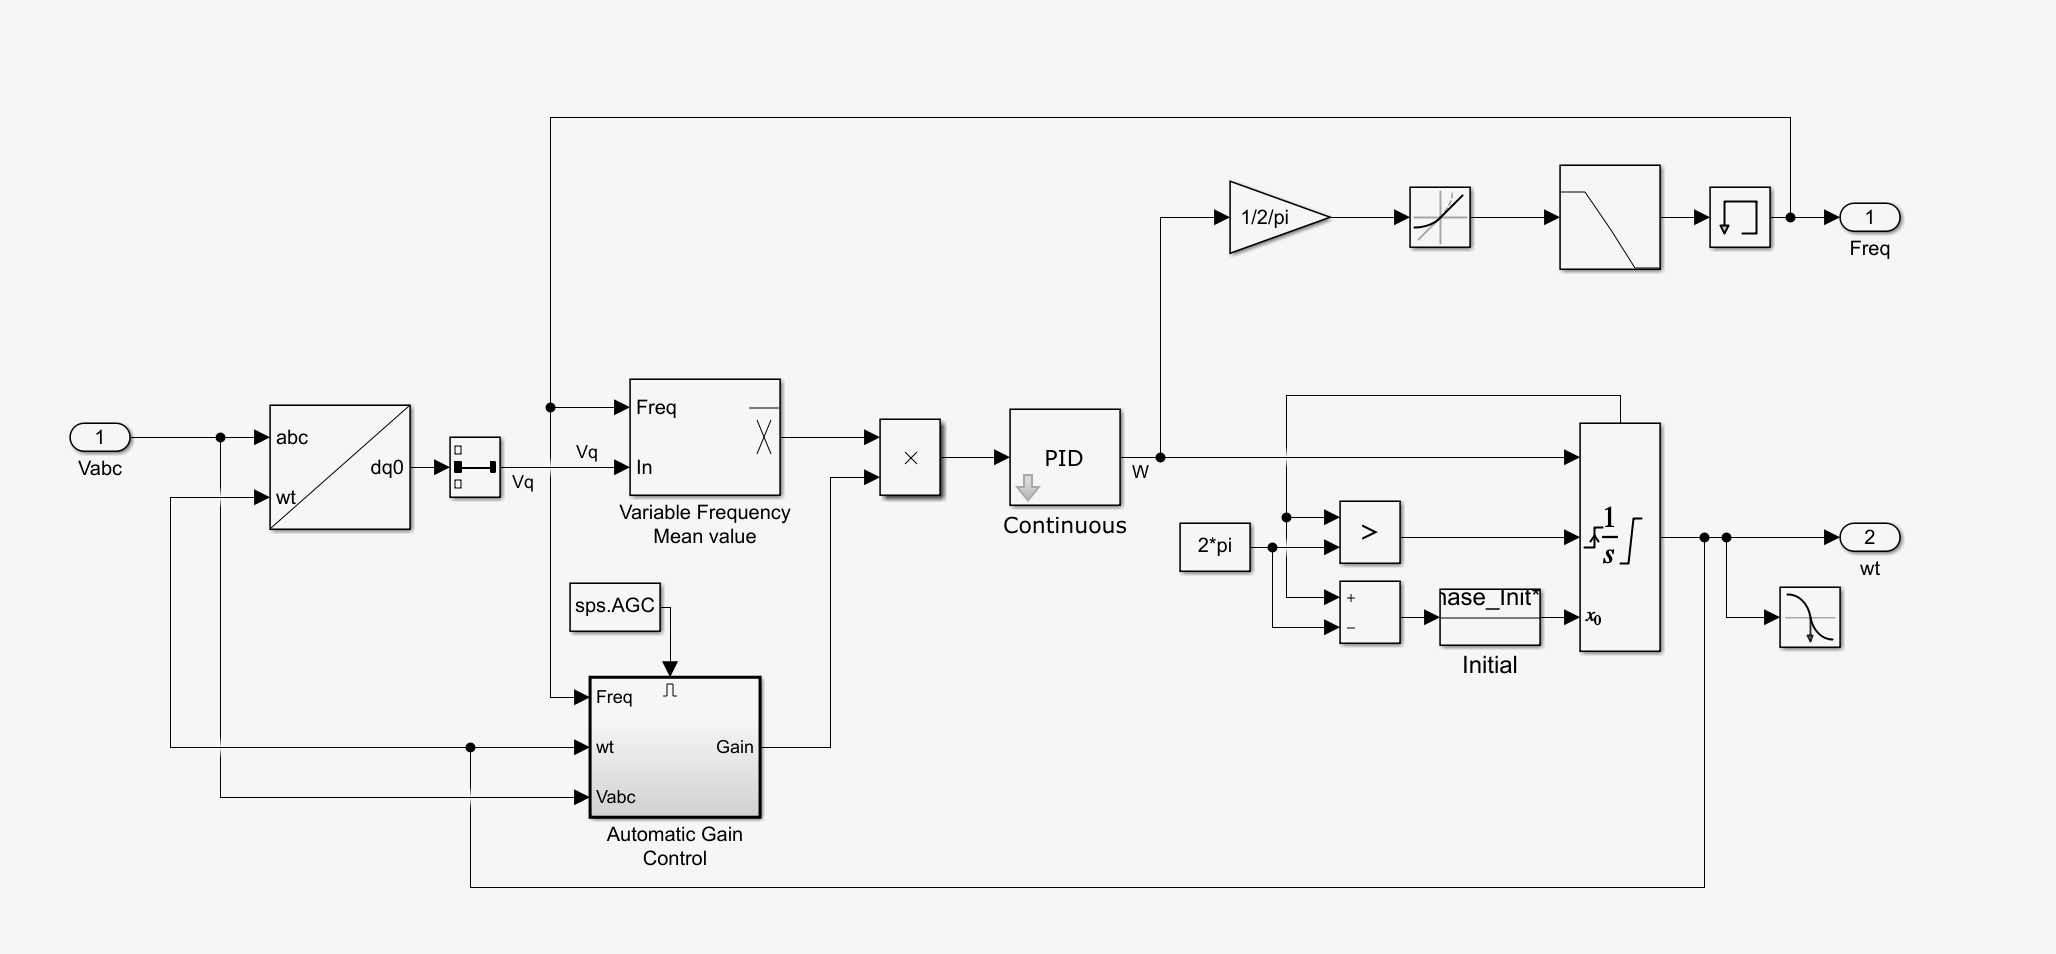

### Control Algorithm

Generally, the control algorithm includes three parts: 

- The maximum power point tracking (MPPT) algorithm

- Boost converter control 

- DC bus control

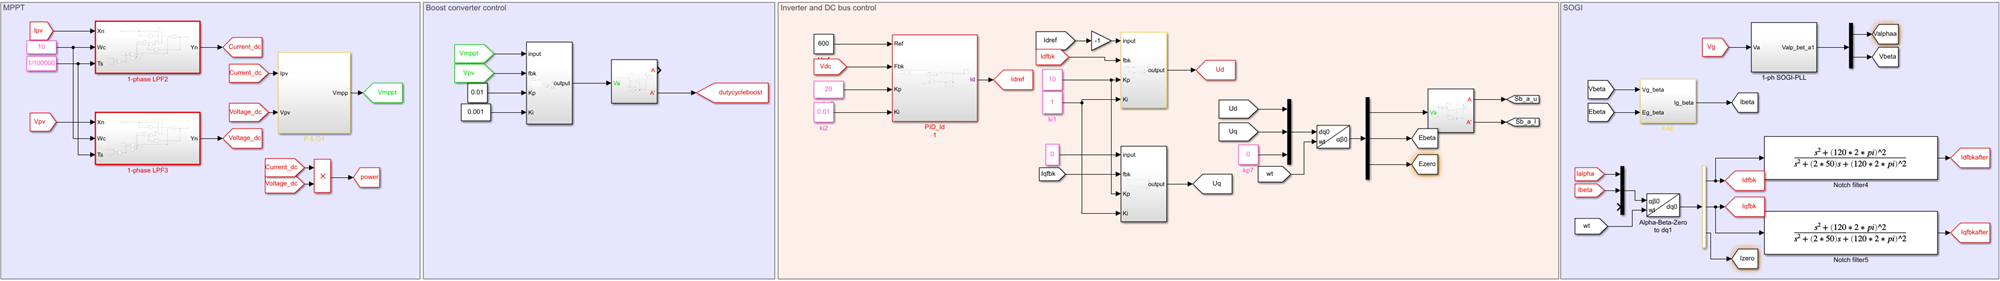

### Maximum Power Point Tracking (MPPT)

**MPPT Control** is a technique commonly used in renewable energy systems, particularly in photovoltaic (PV) solar systems, to optimize the power output from solar panels. Solar panels have a nonlinear relationship between current and voltage, and if we observe the power-voltage curve of the solar panel, we can find that there is always a maximum power point that exists under proper irradiance and temperature conditions. This point is called the maximum power point (MPP).  

There are [two major methods](https://www.mathworks.com/discovery/mppt-algorithm.html) to determine whether the PV system us operating at the MPP: perturbation and observation (P&O) and incremental conductance method. 

MPPT("No Selection")

In this simulation model, the P&O method is used.

### Boost converter control

A **proportional integral (PI) controller **is used to generate the duty cycle of the switch. The higher duty cycle will let the boost converter provide the higher voltage output. Click the button to see more details.

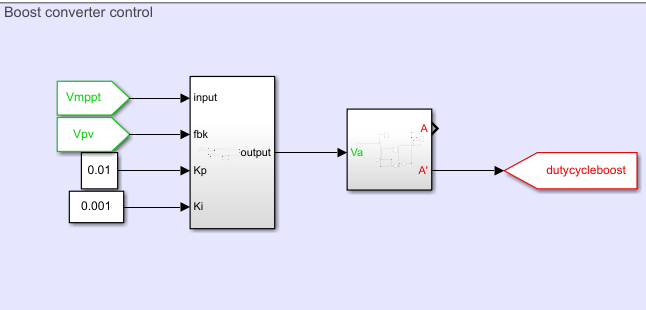


showpic1(true)

### Inverter and DC Bus Control

The inverter control includes two major parts: **current and voltage controller **and **duty cycle generation **. 

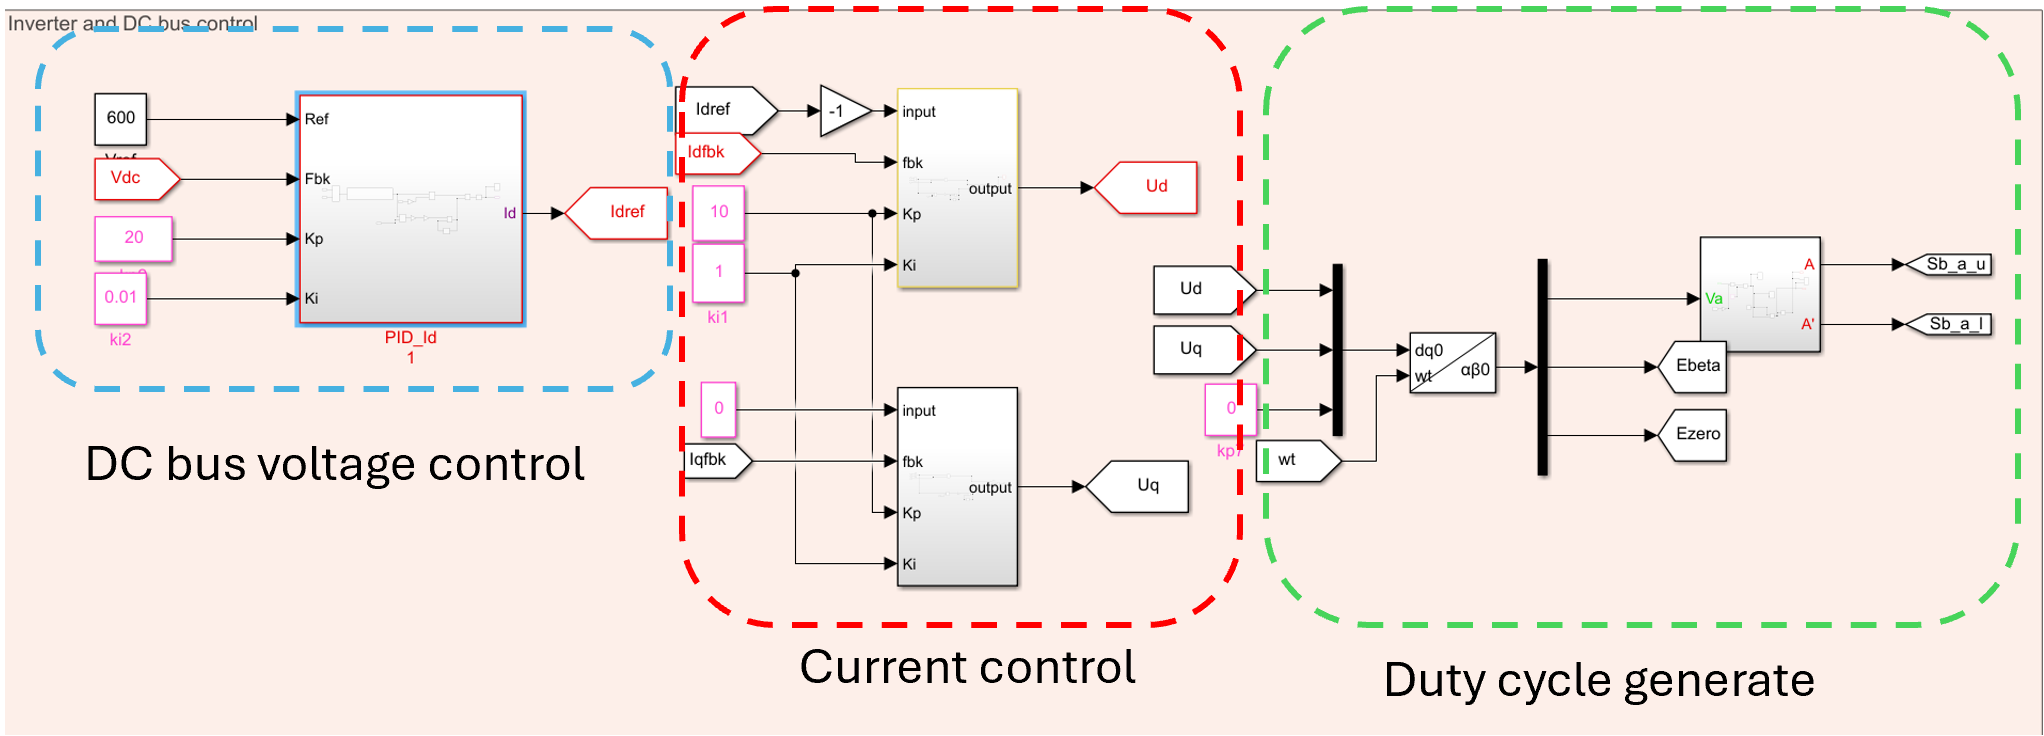

To understand the above three controllers further, use the following drop down menu.

controller("No Selection")

### Second-Order Generalized Integrator (SOGI)

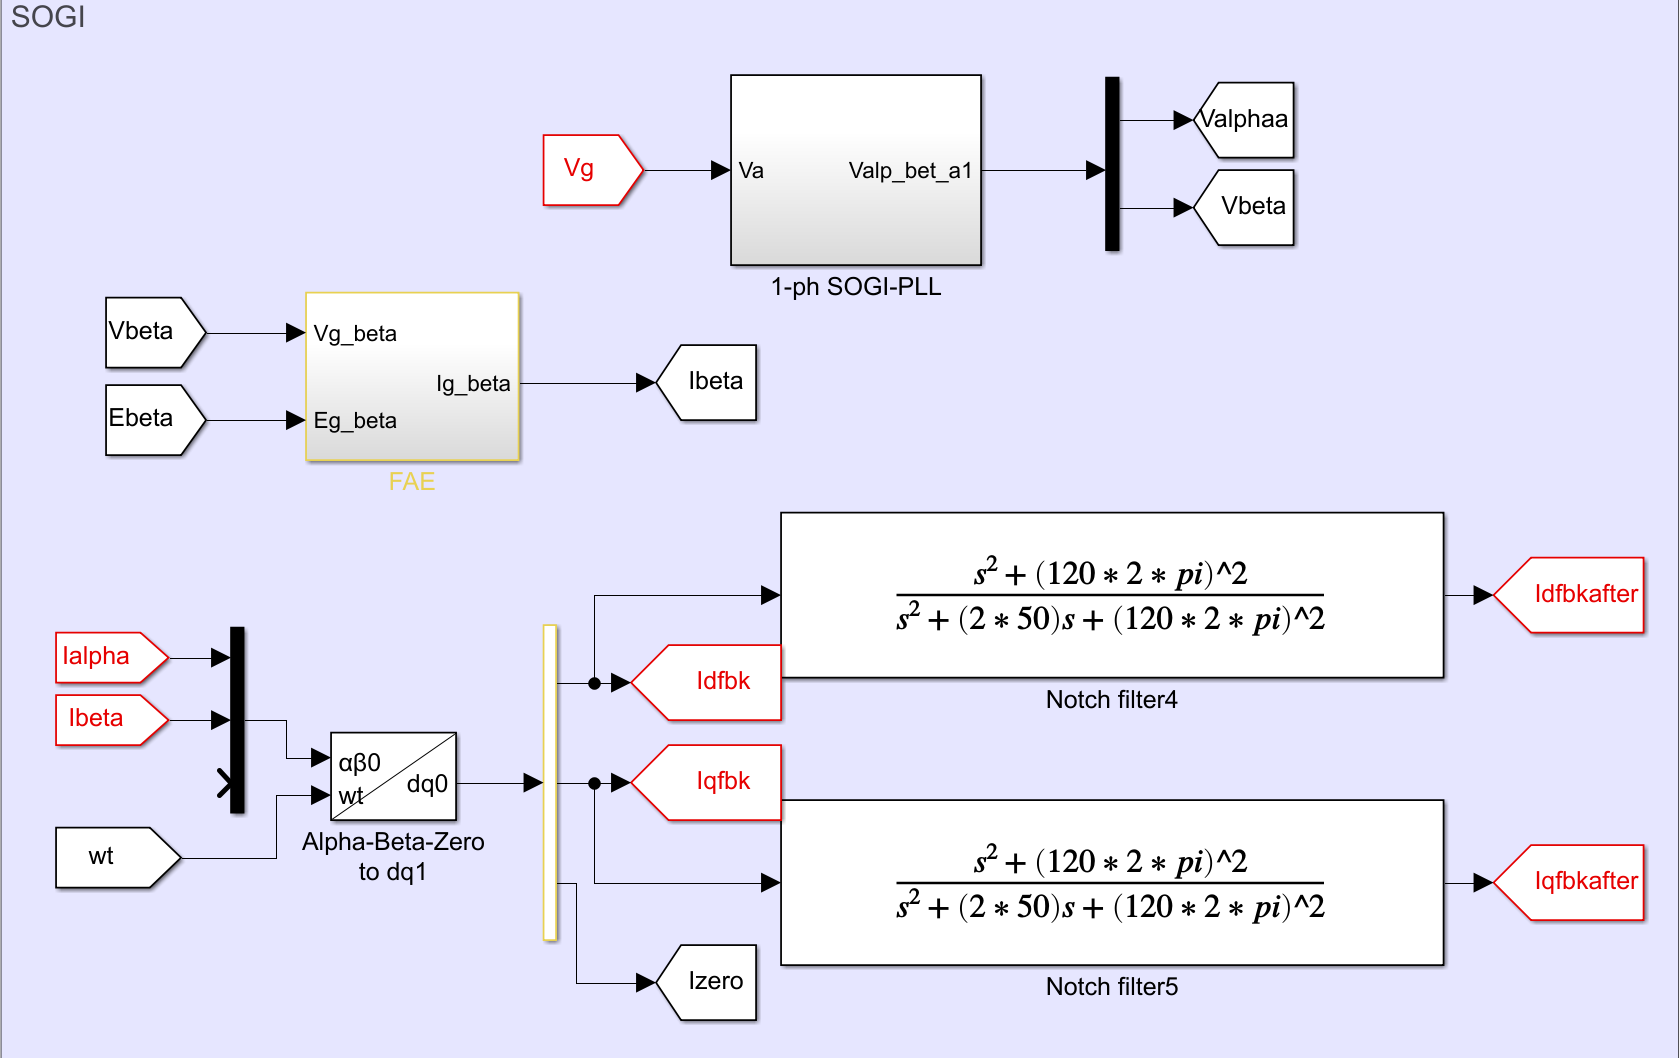

One major difference between a one-phase and three-phase system is that the **alpha,beta-dq transformation** is not complete. Therefore, a virtual beta current will be calculated to make the transformation complete. The increases the performance of the current controllers. SOGI is used to generate the virtual beta voltage. Then, we can use the following equation to calculate the virtual beta current. 

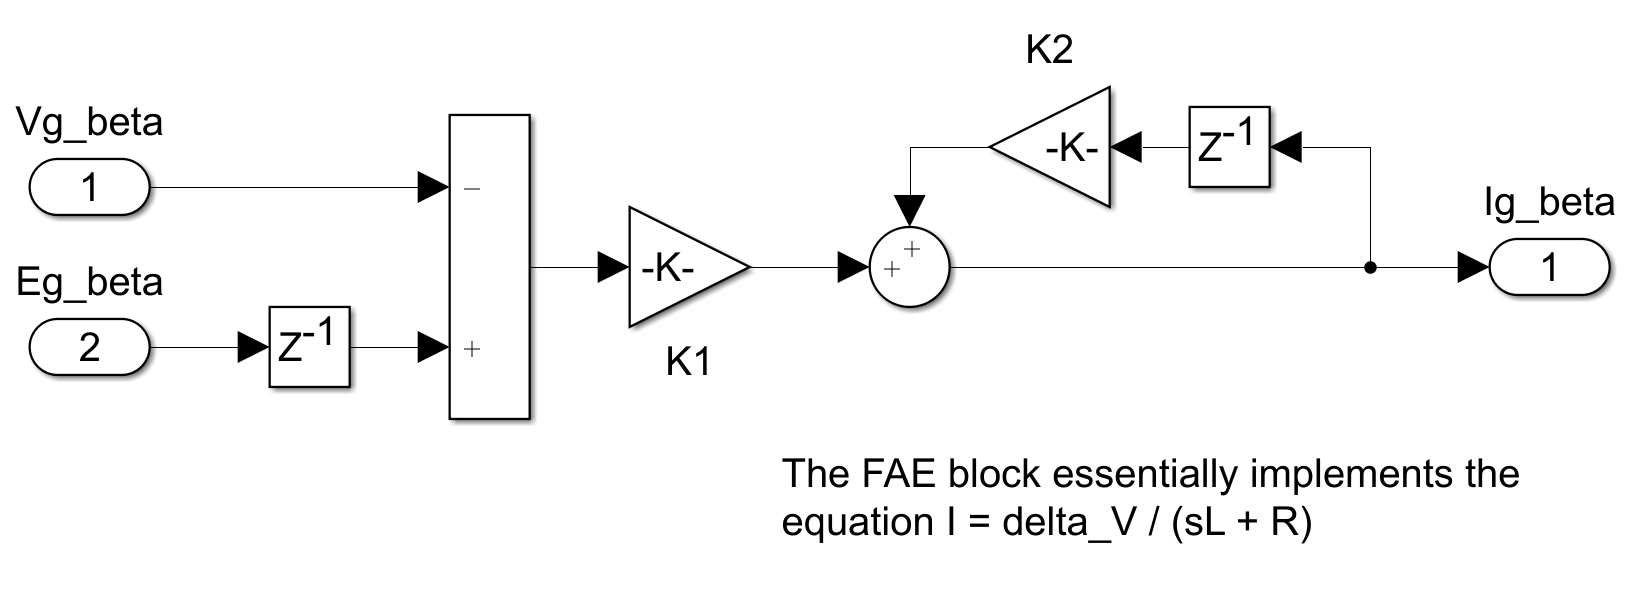

Vg_beta is the voltage generated by the SOGI, the Eg_beta is the voltage calculated from the Inverter. 

## Analyzing Model Results

Run the single-phase solar model. Once the simulation is complete (allow a few minutes), click the scopes to explore the simulation results. 

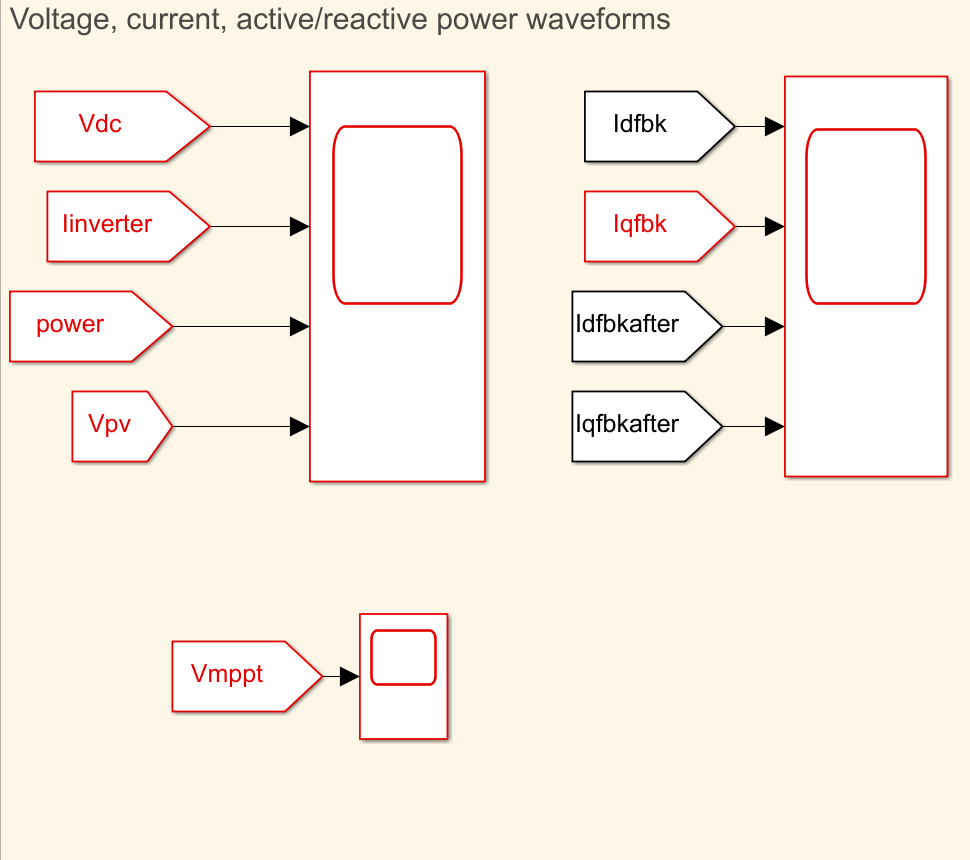

Check the following:

- Is Vdc stable at the MPPT point?

- Is the Inverter current a smooth sine wave?

- Do second order harmonics appear on the DC bus voltage?

If the simulation results satisfy the above rules, it means Id, Iq and Vmppt are stable, which also means the control algorithm is doing its job!  

Select from the following menu to see reference simulation results.

result("No Selection")

## Conclusion

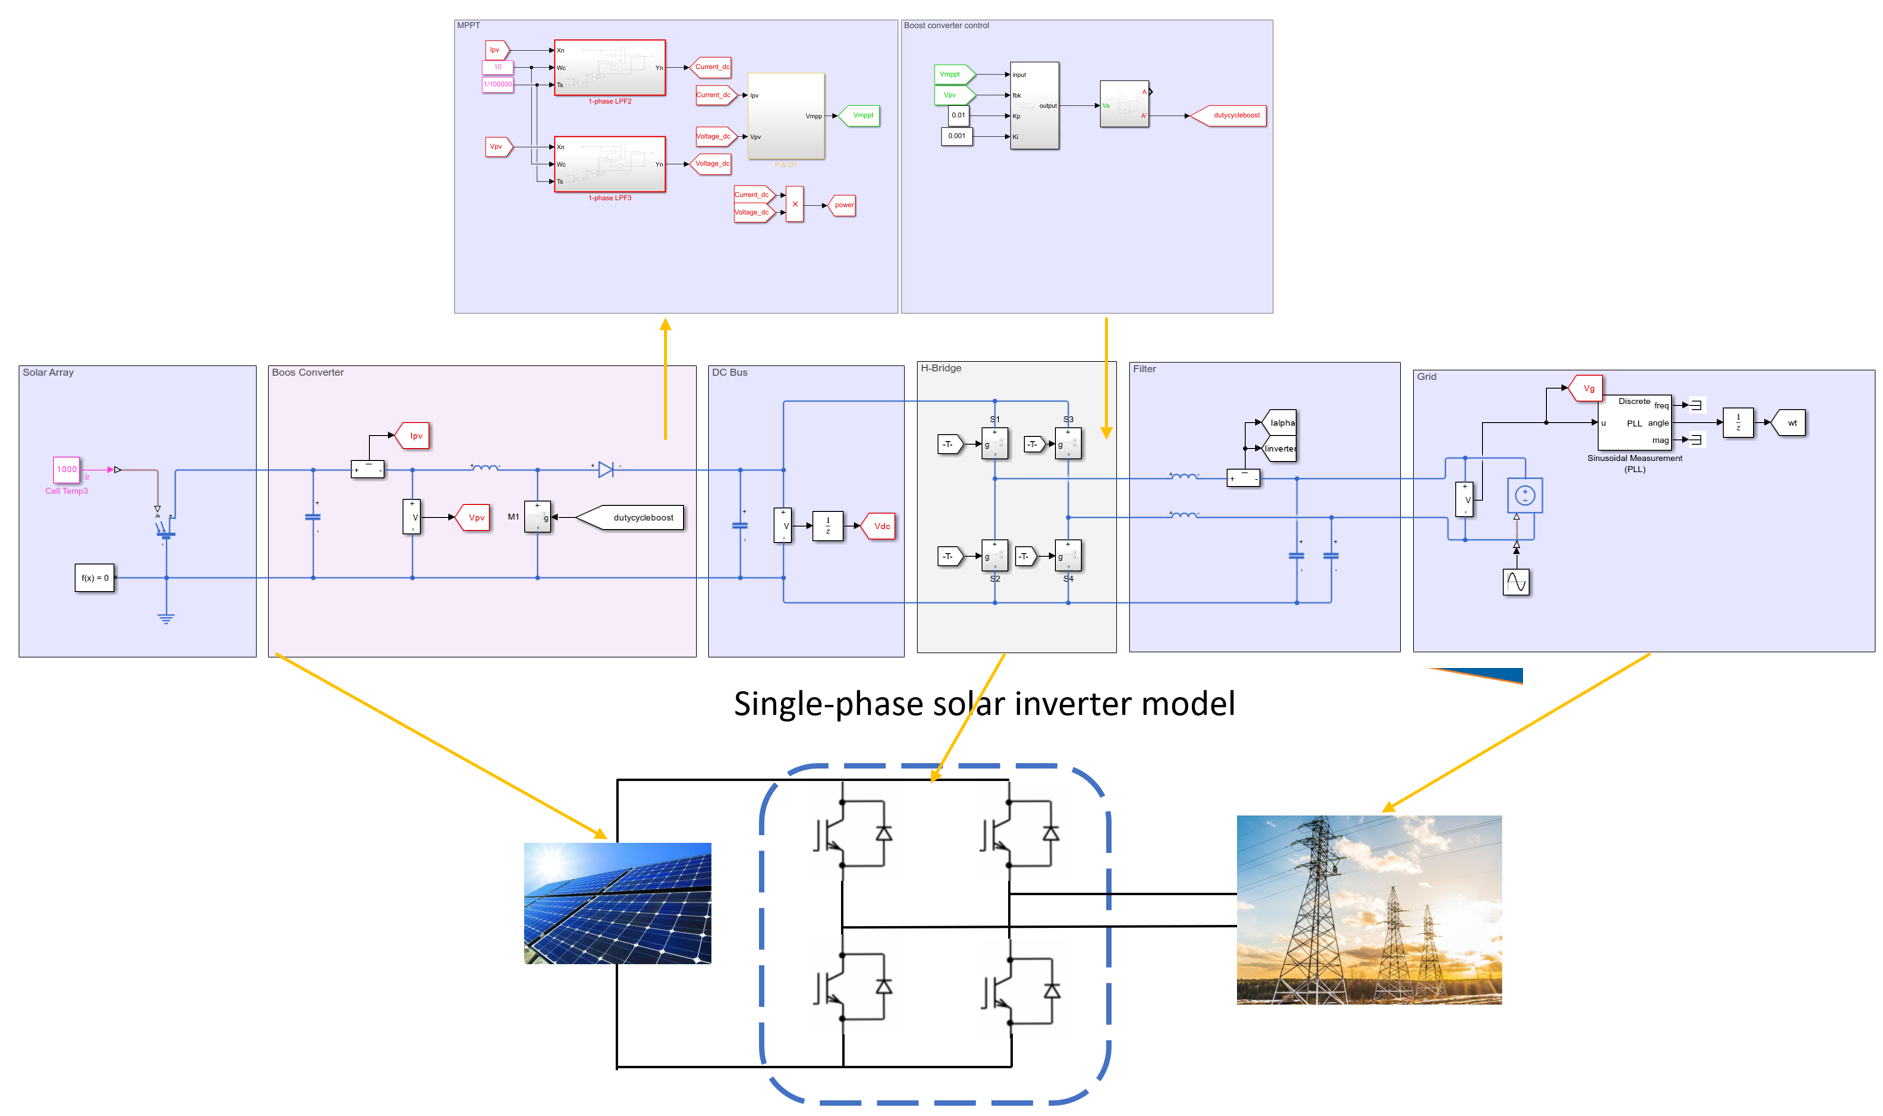

This simulation of the **Single-Phase Photovoltaic (PV) System** demonstrates the practical operation and control of a grid-connected solar power system using MATLAB/Simulink. The model showcases how DC power generated by the PV panel is converted to AC and injected into the grid through an Inverter, while addressing key challenges such as **second-order harmonics** and **unstable MPPT operation**.

Key takeaways from this model include:

- **Pulsating Power Problem**: Single-phase systems inherently suffer from 120 Hz second-order harmonics due to double-frequency oscillations in AC power. These harmonics affect the PV output voltage and MPPT stability.

- **Mitigation Strategy**: The use of a **large capacitor** and a **boost converter** helps to suppress pulsating power and stabilize the DC link voltage. This improves overall power quality and protects PV panel performance.

- **MPPT**: The model employs the P&O algorithm to track the optimal power output point, maximizing energy harvested under varying irradiance and temperature conditions.

- **Inverter and Control Architecture**: The Inverter control consists of DC bus voltage regulation and current control using **PI controllers**, along with **duty cycle generation** for modulation.

- **SOGI Implementation**: To overcome limitations of the αβ-dq transformation in single-phase systems, the model uses a **SOGI** to generate virtual orthogonal signals for better current control performance.

Finally, the inclusion of **interactive sliders** for irradiance and temperature enables users to visualize real-time changes in the I-V and P-V curves, making this an effective tool for understanding PV system behavior under dynamic conditions.

This simulation provides valuable insight into the control, conversion, and optimization processes required for effective integration of PV systems into modern power grids.

## Exercises

 **Exercise 1. Which transformation was used in this model.**

warning("on","all")
exerciseSol1(...
     false, ...
   false);
 

 **Exercise 2. What is the two major control target in the control Algorithm**

exerciseSol2(...
     false, ...
   false,...
  false);
 

 **Exercise 3. Which part of the circuit undermine the pulsating power problem**

exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Solar Panel" "Grid" "Booster-Controller" "Hbridge"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Solar Panel"
        rect = imread("Images/PV.png");
        imshow(rect,'Interpolation',"bilinear");
        fprintf('test')
    elseif opt == "Grid"
        rect = imread("Images/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Booster-Controller"
        rect = imread("Images/BoosterController.png");
        imshow(rect, 'Interpolation', 'bilinear');
    elseif opt == "Hbridge"
        rect = imread("Images/Hbridge.png");
        imshow(rect, 'Interpolation', 'bilinear');
    end
end
end

function MPPT(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "P&O" "Incremental Conductance"])}
end
clf;
if opt == "No Selection"
else
    if opt == "P&O"
        rect = imread("Images/PO.jpg");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Incremental Conductance"
        rect = imread("Images/IC.jpg");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Circuit Parts" "Control Part"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Circuit Parts"
        rect = imread("Images/result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Control Part"
        rect = imread("Images/Result2.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end


function pv_curves(Irradiance, Temperature)
    V = linspace(0, 32.9, 100);  
    T = Temperature + 273;  
    G = Irradiance;
    k = 1.38064852e-23;
    q = 1.602176634e-19;
    Ns = 54;
    Voc_n = 32.9;
    Isc_n = 8.21;
    Rs = 0.2210;
    Rp = 415.405;
    a = 1.3;
    Eg = 1.12;
    KI = 0.0032;
    Ipv_n = 8.21;
    G_n = 1000;
    T_n = 298;
    Vt = Ns * k * T / q;
    
    I0 = calculate_saturation_current(T, T_n, Isc_n, Voc_n, Eg, a);
    Ipv = calculate_pv_current(Ipv_n, KI, (T - T_n), G, G_n);
    
 
    I_values = arrayfun(@(v) calculate_current(Ipv, I0, Rs, Rp, v, Vt, a), V);
    
  
    P = V .* I_values;
    
    figure('Position', [100, 100, 1200, 400]);  
    subplot(1, 2, 1); 
    plot(V, I_values, 'b', 'LineWidth', 2); 
    title('I-V Curve');
    xlabel('Voltage (V)');
    ylabel('Current (A)');
    grid on;
    ylim([0 10]);
 
    
    subplot(1, 2, 2);  
    plot(V, P, 'r', 'LineWidth', 2);  
    title('P-V Curve');
    xlabel('Voltage (V)');
    ylabel('Power (W)');
    grid on;
    ylim([0 220]);
   

end

function I0 = calculate_saturation_current(T, Tn, Iscn, Vocn, Eg, a)
    k = 1.38064852e-23;  
    q = 1.602176634e-19;  
  
    Vt_n = 54*k * Tn / q;  
    I0n = Iscn / (exp(Vocn / (a * Vt_n)) - 1);
    
    I0 = I0n * (Tn / T)^3 * exp(q * Eg / (a * k) * (1 / Tn - 1 / T));
end

function Ipv = calculate_pv_current(Ipv_n, KI, DeltaT, G, Gn)
    Ipv = (Ipv_n + KI * DeltaT) * (G / Gn);
end


function I = calculate_current(Ipv, Io, Rs, Rp, V, Vt, a)
    options = optimset('Display', 'off', 'TolX', 1e-6, 'TolFun', 1e-6);
    f = @(I) Ipv - Io * (exp((V + Rs * I) / (Vt * a)) - 1) - (V + Rs * I) / Rp - I;
    I = fzero(f, Ipv, options);
end

function exerciseSol1(A,B)
    
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        warning("Please select an answer!")
    elseif A && B
        warning("Please select only one answer")
    elseif A
        disp("Correct!")
    else 
        warning("Incorrect. please review the inverter control section.")
    end
end

function exerciseSol2(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif A && B
        warning("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. Please check the control part again")
    end
end
function exerciseSol3(A,B,C)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        warning("Please select all that apply!")
    elseif B&&C
        disp("Correct!")
    elseif B
        warning("Please select all that apply!")
    elseif C
        warning("Please select all that apply!")
    else 
        warning("Incorrect.")
    end
end

function showpic1(A)

    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/booster.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end

function runmodel_onephasePV(simOut)
    warning('off', 'all');

    try
   
        time      = simOut.tout;
        vdc_val   = simOut.Vdc;
        iinv_val  = simOut.Iinverter;
        power_val = simOut.power;
        vpv_val   = simOut.Vpv;

   
        N = min([length(time), length(vdc_val), length(iinv_val), length(power_val), length(vpv_val)]);
        time      = time(1:N);
        vdc_val   = vdc_val(1:N);
        iinv_val  = iinv_val(1:N);
        power_val = power_val(1:N);
        vpv_val   = vpv_val(1:N);


        figure('Position', [100, 100, 1000, 800]);

        subplot(2,2,1);
        plot(time, vdc_val, 'b', 'LineWidth', 1.5);
        title('DC Output Voltage'); xlabel('Time (s)'); ylabel('V_{dc} (V)'); grid on;

        subplot(2,2,2);
        plot(time, iinv_val, 'r', 'LineWidth', 1.5);
        xlim([0.3, 0.5]);
        title('Inverter Current'); xlabel('Time (s)'); ylabel('I_{inverter} (A)'); grid on;

        subplot(2,2,3);
        plot(time, power_val, 'k', 'LineWidth', 1.5);
        title('Output Power'); xlabel('Time (s)'); ylabel('P_{out} (W)'); grid on;

        subplot(2,2,4);
        plot(time, vpv_val, 'm', 'LineWidth', 1.5);
        title('PV Voltage'); xlabel('Time (s)'); ylabel('V_{pv} (V)'); grid on;

    catch ME
        disp('❌ Error occurred during plotting:');
        disp(ME.message);
    end
end

